clearvars
[data] = readRadioSondeData('C:\Users\Level1Zach\Desktop\Hodograph_test\eclipseData\W8_L1_1100UTC_072220_ZASUS_Profile.txt');

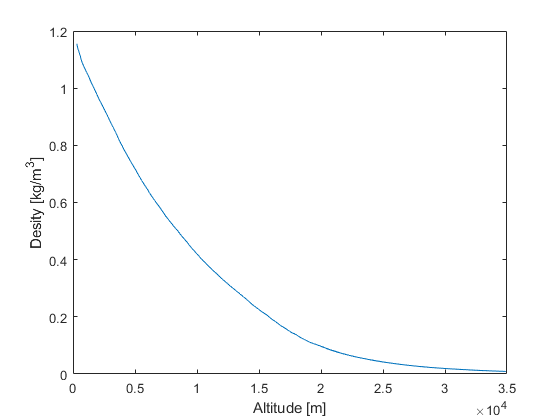

% [data] = readRadioSondeData('C:\Users\Level1Zach\Desktop\Hodograph_test\eclipseData\W10_L1_1500UTC_072920_Artemis_Profile.txt');

figure(2)
plot(data.Alt,data.D);
xlabel('Altitude [m]'); ylabel('Desity [kg/m^3]')

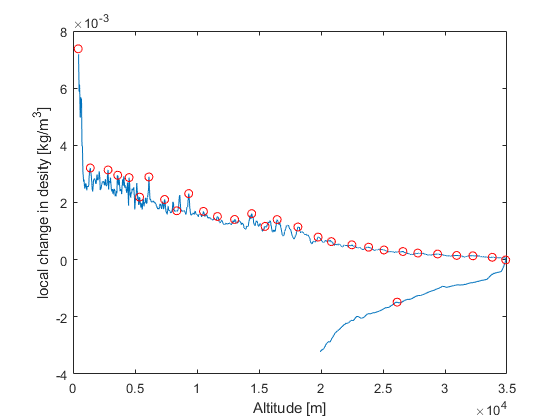

D = data.D(5:end);
Alt = data.Alt(5:end);
[lmxt,P] = islocalmax(D);

for i = 6:length(lmxt)
    dD(i) = D(i-5)-D(i);
end
dD=dD.';
N = normalize(dD,'zscore','robust');
[pks,locs] = findpeaks(dD,'MinPeakDistance',125);
figure(3)
plot(Alt(8:end),dD(8:end),Alt(locs),pks,'or');
xlabel('Altitude [m]'); ylabel('local change in desity [kg/m^3]')